clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_3_16.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';
% network = '_seal_pred_filtered_torque_colon_9_26.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];


      joint_path = ['../../../test_Penn/csv/test/'];
      jacobian_path = ['../../../test_Penn/csv/test/', data, '/jacobian/'];
      torque_path = ['../../../test_Penn/csv/test/', 'free_spacelstm_delta__true_filtered_torque.csv'];
%       joint_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/joints/'];
%       jacobian_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/jacobian/'];
%       torque_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/', 'lstm', network];

% joint_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', 'psm1_mary_1', '/', data, '/joints/'];
% jacobian_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/',  test_folder, '/', 'psm1_mary_1', '/', data, '/jacobian/'];
% torque_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', 'psm1_mary_1', '/', data, '/', 'lstm', network];

joint_data = readmatrix([joint_path, 'free_spacelstm_delta__pred_filtered_torque.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian.csv']);
torque_data = readmatrix(torque_path);

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =     0.0000    0.0000   -0.2485   -0.0000    0.0722    0.0723
   -0.0000   -0.0000    0.3843   -0.0000   -0.0546    0.0831
   -0.0000    0.0000   -0.8892    0.0000   -0.0438    0.0157
    0.0000   -0.9631         0   -0.2485    0.6500   -0.7185
   -1.0000    0.0000         0    0.3843    0.7467    0.5435
    0.0000    0.2691         0   -0.8892    0.1411    0.4339



fs_pred_torque = torque_data(:,1:6).';
% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(fs_pred_torque),1:6).';
jacobian = jacobian(:,:,1:length(fs_pred_torque));

fs_diff = measured_torque - fs_pred_torque;
fs_force = zeros(6,length(fs_pred_torque));

%%%%% si
force_sensor_cal = [-0.88379, -0.37356, -0.2714676; -0.15279, 0.929125, 0.32620139; 0.098968, -0.33537, -0.9366509]

force_sensor_cal =    -0.8838   -0.3736   -0.2715
   -0.1528    0.9291    0.3262
    0.0990   -0.3354   -0.9367


%%%% classic
force_sensor_cal = [0.971011, 0.158129, -0.177306; 0.091309, -0.97246, 0.10079652; -0.04083, -0.13805, -0.9768911] 

force_sensor_cal =     0.9710    0.1581   -0.1773
    0.0913   -0.9725    0.1008
   -0.0408   -0.1381   -0.9769




force_sensor_cal = force_sensor_cal.'

force_sensor_cal =     0.9710    0.0913   -0.0408
    0.1581   -0.9725   -0.1381
   -0.1773    0.1008   -0.9769


[U, S, V] = svd(force_sensor_cal);
force_sensor_cal = U * V.'

force_sensor_cal =     0.9854    0.1375   -0.1006
    0.1241   -0.9838   -0.1297
   -0.1168    0.1153   -0.9864


force_sensor_cal = V * U.'

force_sensor_cal =     0.9854    0.1241   -0.1168
    0.1375   -0.9838    0.1153
   -0.1006   -0.1297   -0.9864



angle = -pi/4;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]

Ra =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071]

Rz =    -1.0000         0         0
         0   -0.7071   -0.7071
         0   -0.7071    0.7071


% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz)

ans = 1.0000


for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(jacobian(:,:,i).') * (fs_diff(:,i));
    fs_force(1:3, i) =Ra *fs_force(1:3, i);
end

fs_force = fs_force.';


real_force_path = ['../../../test_Penn/csv/', 'sensor/'];
% real_force_path = ['dvrk-si-3-15/csv_si/', 'sensor/'];
% real_force_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', 'psm1_mary_1', '/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);

% plot(real_force_data(:,1), real_force_data(:,2), 'b')
clf;







windowSize = 20; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

% fs_force = filter(b,a,fs_force);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));
loss_taux = mean(sqrt(mean( (fs_force(:,4) - real_force(:,4)).^2 )));
loss_tauy = mean(sqrt(mean( (fs_force(:,5) - real_force(:,5)).^2 )));
loss_tauz = mean(sqrt(mean( (fs_force(:,6) - real_force(:,6)).^2 )));

[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix)

boundX = 8.2039

[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy)

boundY = 3.6692

[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz)

boundZ = 3.8997

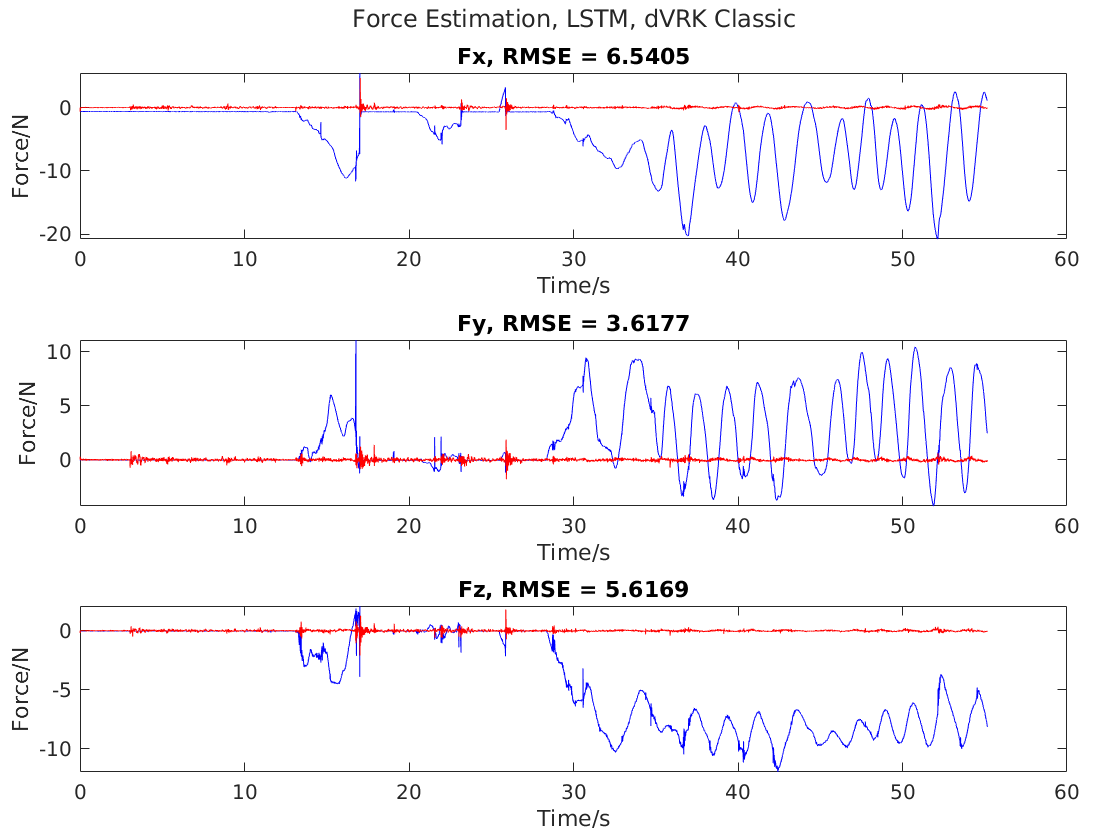



figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Force Estimation, LSTM, dVRK Classic'))

nexttile
plot(0.005 * (1:length(fs_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(0.005 * (1:length(fs_force)), fs_force(:,1), 'r')
xlabel('Time/s')
ylabel('Force/N')
hold off

nexttile
plot(0.005 * (1:length(fs_force)), real_force(:,2), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(0.005 * (1:length(fs_force)), fs_force(:,2), 'r')
xlabel('Time/s')
ylabel('Force/N')
hold off

nexttile
plot(0.005 * (1:length(fs_force)), real_force(:,3), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(0.005 * (1:length(fs_force)), fs_force(:,3), 'r')
xlabel('Time/s')
ylabel('Force/N')
hold off

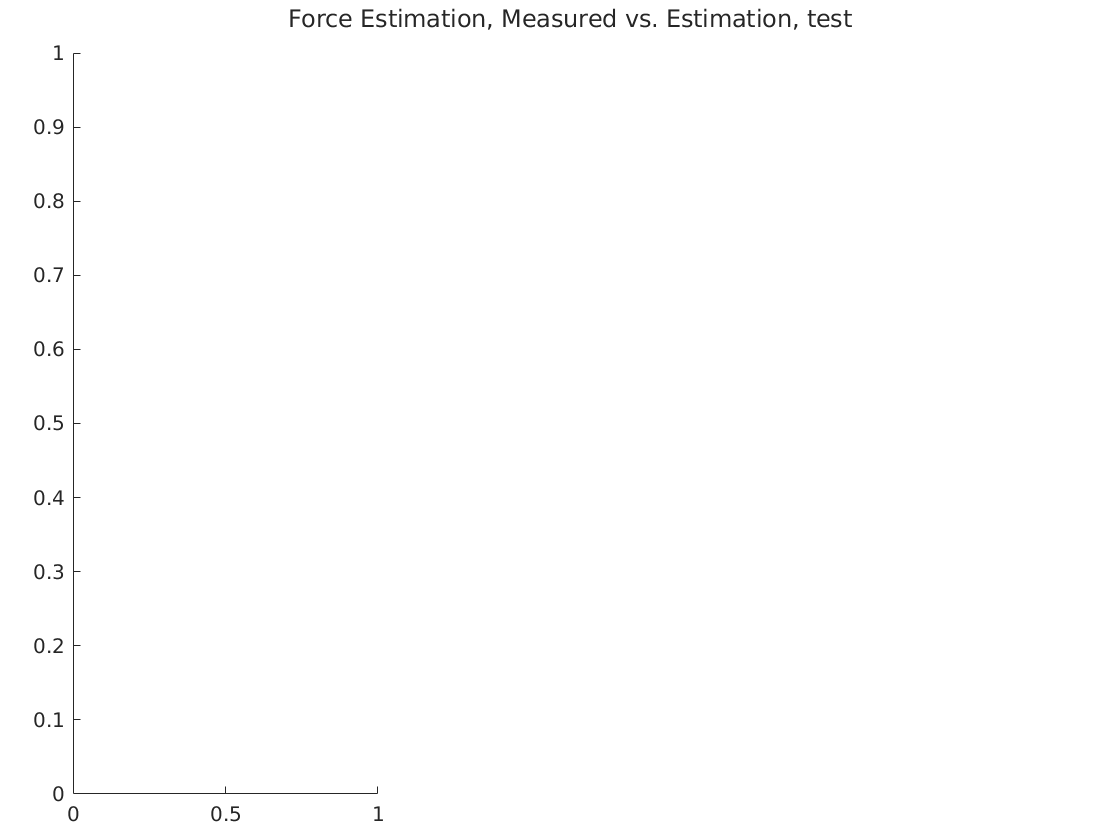

clf;
figure()
tcl = tiledlayout(1,3, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Force Estimation, Measured vs. Estimation, %s', test_folder))



nexttile
hold on


kksk = corrcoef(real_force_ft(:,1), fs_force_ft(:,1))

Reference to a cleared variable real_force_ft.

[RHO,PVAL] = corr(real_force_ft(:,1),fs_force_ft(:,1),'Type','Spearman');
title(sprintf('Fx, Rho: %.4f', RHO))

data = [real_force_ft(:,1), 1*(fs_force_ft(:,1))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal
grid on
hold off

nexttile
hold on
kksk = corrcoef(real_force_ft(:,2), fs_force_ft(:,2))
[RHO,PVAL] = corr(real_force_ft(:,2),fs_force_ft(:,2),'Type','Spearman');
title(sprintf('Fy, Rho: %.4f', RHO))

data = [real_force_ft(:,2), 1*(fs_force_ft(:,2))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal
grid on
hold off

nexttile
hold on
kksk = corrcoef(real_force_ft(:,3), fs_force_ft(:,3))
[RHO,PVAL] = corr(real_force_ft(:,3),fs_force_ft(:,3),'Type','Spearman');
title(sprintf('Fz, Rho: %.4f', RHO))

data = [real_force_ft(:,3), 1*(fs_force_ft(:,3))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal
grid on
hold off







function density_2D = density2D_KD(data,radius)
% function: use KD tree to extract scatter 2D density features
% input: data - original data(m*3)    
% output：planes - plane parameters through fitting
M = size(data,1);
density_2D = zeros(M,1);
idx = rangesearch(data(:,1:2),data(:,1:2),radius,'Distance','euclidean','NSMethod','kdtree');
for i = 1:M
    density_2D(i,1) = length(idx{i})/(pi*radius^2);
end
end



